# Amelia Rotondo - 887925113

# IC - Computation - IC056

## Problem 1.

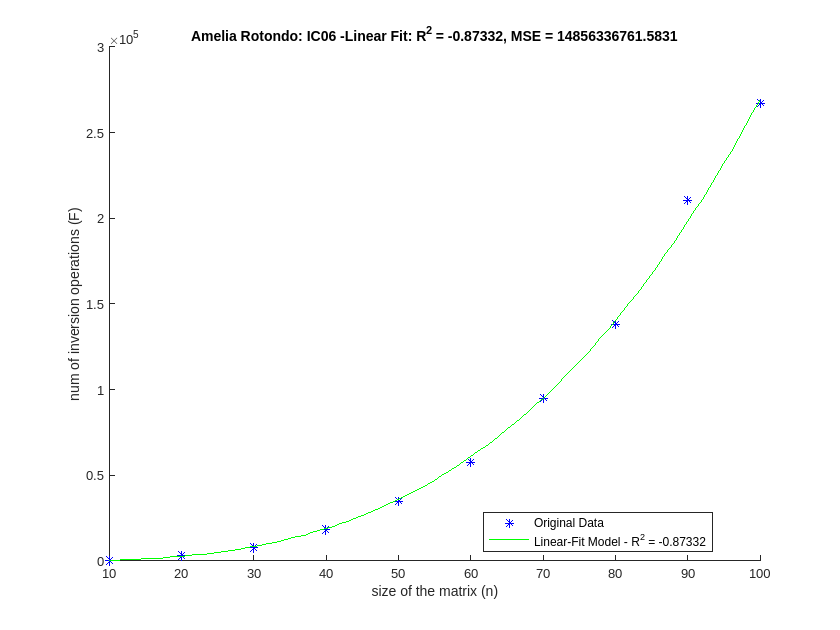

% Initialize Data 
n = [10 20 30 40 50 60 70 80 90 100];
f = [397 3452 7826 18475 34512 57251 94832 137841 210548 267145];
nn = min(n):1:max(n);

% Linearize the Model: F = CN + D
N = n;
NN = nn;
F = f ./ (n.^2);
CD = polyfit(N, F, 1);
ff = polyval(CD, NN);
NN = nn;
FF = ff.*(NN.^2);
F_rsq = myRsq(f, ff);
F_mse = myMse(f, ff);

% Add a Degree-3 Polynomial for Comparisson 
f3 = polyfit(n, f, 3);
ff3 = polyval(f3, nn);
f3_rsq = myRsq(f, ff3);
f3_mse = myMse(f, ff3);

% Plot 1 for the Linear Fit
figure(1); clf; hold on;
fit_title = append('Amelia Rotondo: IC06 -Linear Fit: R^2 = ', num2str(F_rsq), ', MSE = ', num2str(F_mse));
fit_name = append('Linear-Fit Model - R^2 = ', num2str(F_rsq));
plot(n, f, 'b*', 'DisplayName', 'Original Data');
plot(NN, FF, 'g', 'DisplayName', fit_name);
hold off;
title(fit_title);
xlabel('size of the matrix (n)');
ylabel('num of inversion operations (F)');
legend('Location', 'best');

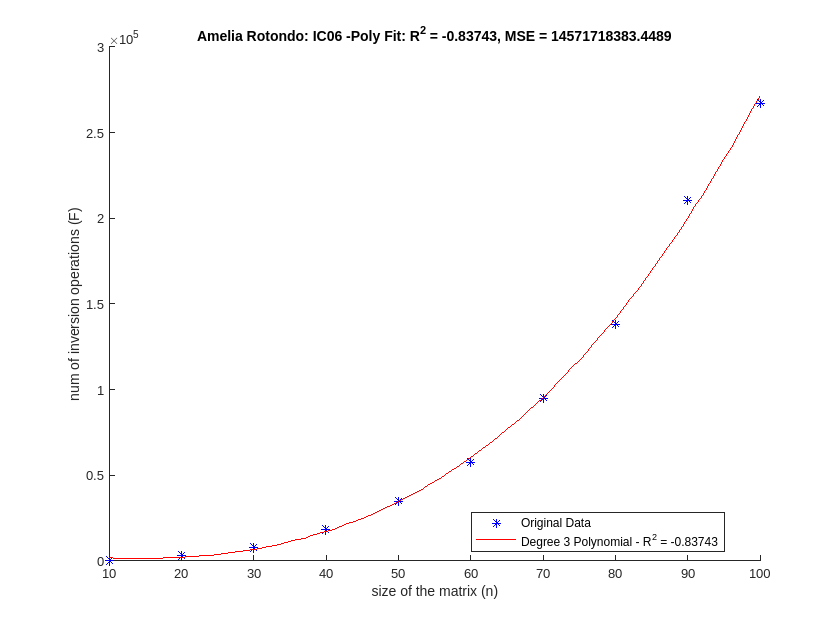


% Plot 2 for the Polynomial
figure(2); clf; hold on;
poly_title = append('Amelia Rotondo: IC06 -Poly Fit: R^2 = ', num2str(f3_rsq), ', MSE = ', num2str(f3_mse));
poly_name = append('Degree 3 Polynomial - R^2 = ', num2str(f3_rsq));
plot(n, f, 'b*', 'DisplayName', 'Original Data');
plot(nn, ff3, 'r', 'DisplayName', poly_name);
hold off;
title(poly_title);
xlabel('size of the matrix (n)');
ylabel('num of inversion operations (F)');
legend('Location', 'best');